% Función de transformación - paso bajo a paso alto
% filipuzzi, fernando rafael
% fecha: 20221024
% matlab2021b21b

function [B,A]=mi_lp2hp(Bs,As, wc)

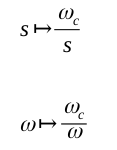

    
    syms s;
    H(s)=poly2sym(Bs,s)/poly2sym(As,s);

    H(s)=collect(H(wc/s));
    
    [num,den]=numden(H(s));
    B=sym2poly(num);
    A=sym2poly(den);

end